clc; clear; clf;
darker_color = 0.5;
colors = [1 0 0; darker_color 0 0; 0 1 0; 0 darker_color 0; 0 0 1; 0 0 darker_color];

data_names = ["$a_x$", "$a_y$", "$a_z$", "$\alpha_x$", "$\alpha_y$", "$\alpha_z$"];
data_names_cleaned = ["$a_{x, cleaned}$", "$a_{y, cleaned}$", "$a_{z, cleaned}$", "$\alpha_{x, cleaned}$", "$\alpha_{y, cleaned}$", "$\alpha_{z, cleaned}$"];

### Raw Accleration Data

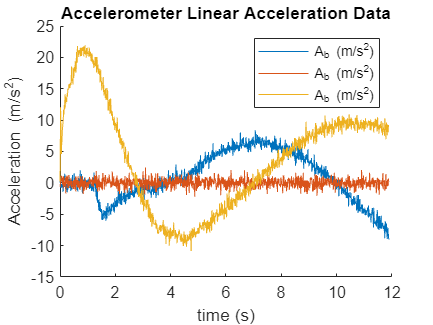

load("Acceleration Data.mat") % load noisy acceleration data

figure
hold on
plot(AccelerationData(:,1), AccelerationData(:, 2), DisplayName='A_x_b (m/s^2)') % x acceleration
plot(AccelerationData(:,1), AccelerationData(:, 3), DisplayName='A_y_b (m/s^2)') % y acceleration
plot(AccelerationData(:,1), AccelerationData(:, 4), DisplayName='A_z_b (m/s^2)') % z acceleration
ylabel('Acceleration (m/s^2)'); xlabel('time (s)'); title('Accelerometer Linear Acceleration Data')
legend('location','NorthEast')
hold off

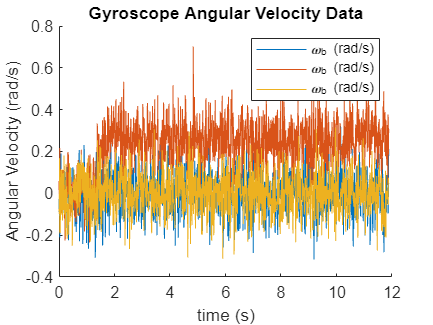


figure
hold on
plot(AccelerationData(:,1),AccelerationData(:,5))
plot(AccelerationData(:,1),AccelerationData(:,6))
plot(AccelerationData(:,1),AccelerationData(:,7))
ylabel('Angular Velocity (rad/s)'); xlabel('time (s)'); title('Gyroscope Angular Velocity Data')
legend('\omega_x_b (rad/s)','\omega_y_b (rad/s)','\omega_z_b (rad/s)','location','NorthEast')
hold off

### Cleaned Data

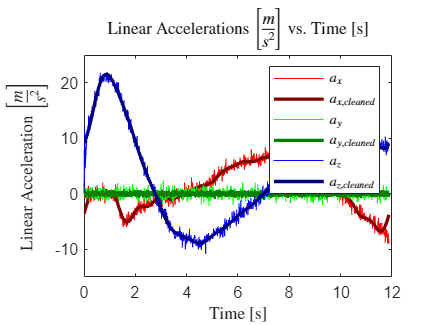

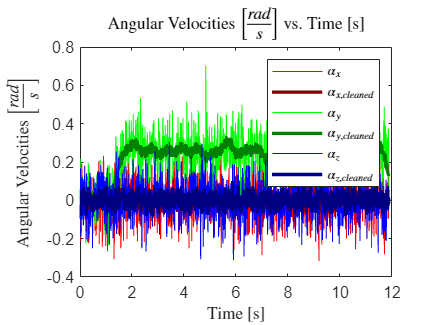

time = AccelerationData(:,1); % time vector, [s]
cleaned_Acceleration_Data = [];

Fs = find(time==1) - find(time==0); % sampling frequency, [Hz]
N = length(time); % number of samples
L = 1:floor(N/2); % vector to plot first half of FFT
freq = (0:N-1)*(Fs/N); % frequency vector (Hz)

% Clean (& Plot) Acceleration Data
[rows, cols] = size(AccelerationData);
for col = 2:7 % 1st column is time
    FFT = fft(AccelerationData(:,col), N); % fft of noisy signal
    PSD = FFT.*conj(FFT)/N; % PSD
    choice = 0; % decide whether to keep certain percentage of frequencies or certain count
    switch choice
        case 0
            percentage_to_keep = 2/100; % percentage of greatest amplitude frequencies to use
            indices = PSD>=min(maxk(PSD, floor(percentage_to_keep*length(PSD)))); % indices of most significant frequencies
        case 1
            number_to_keep = 11;
            indices = PSD>=min(maxk(PSD, number_to_keep));
    end
    FFT_cleaned = FFT.*indices;
    data_cleaned = ifft(FFT_cleaned);
    cleaned_Acceleration_Data = [cleaned_Acceleration_Data data_cleaned];
    if (col <= 4)
        figure(1)
        plot(time, AccelerationData(:, col), DisplayName=data_names(col-1))
        hold on
        plot(time, data_cleaned, LineWidth=2, DisplayName=data_names_cleaned(col-1))
        colororder(colors)
        title("Linear Accelerations $\left[\frac{m}{s^2}\right]$ vs. Time [s]", Interpreter="latex")
        legend(Interpreter="latex")
        xlabel("Time [s]", Interpreter="latex")
        ylabel("Linear Acceleration $\left[\frac{m}{s^2}\right]$", Interpreter="latex")
    else
        figure(2)
        plot(time, AccelerationData(:, col), DisplayName=data_names(col-1))
        hold on
        plot(time, data_cleaned, LineWidth=2, DisplayName=data_names_cleaned(col-1))
        colororder(colors)
        title("Angular Velocities $\left[\frac{rad}{s}\right]$ vs. Time [s]", Interpreter="latex")
        legend(Interpreter="latex")
        xlabel("Time [s]", Interpreter="latex")
        ylabel("Angular Velocities $\left[\frac{rad}{s}\right]$", Interpreter="latex")
    end
end


save("Cleaned Acceleration Data", "cleaned_Acceleration_Data")